clc; clear;
dsFolder = "p_dataset_26";
subFolder = ["Sample1", "Sample2", "Sample3", "SampleA", "SampleB", "SampleC"];
categories = ["1", "2", "3", "A", "B", "C"];

allData = table('Size', [0, 2], 'VariableTypes', {'cell', 'cell'}, 'VariableNames', {'Image', 'Label'});

for i = 1:length(subFolder)
    folderPath = fullfile(dsFolder, subFolder(i));
    matFiles = dir(fullfile(folderPath, "*.mat"));

    for j = 1:length(matFiles)
        matFilePath = fullfile(folderPath, matFiles(j).name);
        image = load(matFilePath).imageArray;
        
        allData = [allData; {image, categories(i)}];
    end
end

% convert images to features
numImages = size(allData, 1);
imageSize = size(allData.Image{1});
features = zeros(numImages, prod(imageSize));

for i = 1:numImages
    image = allData.Image{i};
    features(i, :) = image(:)';
end

labels = categorical(allData.Label);

% split data into training and test set
cv = cvpartition(labels, 'HoldOut', 0.2);
idx = cv.test;
trainIdx = training(cv);
testIdx = test(cv);
trainFeatures = features(trainIdx, :);
trainLabels = labels(trainIdx, :);
testFeatures = features(testIdx, :);
testLabels = labels(testIdx, :);

% Train an SVM classifier
svmClassifier = fitcecoc(trainFeatures, trainLabels);

% Predict labels for the test set
predictedLabels = predict(svmClassifier, testFeatures);

% Evaluate the classifier's performance
confusionMatrix = confusionmat(testLabels, predictedLabels);
accuracy = sum(diag(confusionMatrix)) / sum(confusionMatrix(:));

fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 98.93%


% Calculate precision, recall, and F1-score
confusionMatrix = confusionmat(testLabels, predictedLabels)

confusionMatrix =    202     0     0     1     0     0
     0   202     0     0     1     0
     1     0   202     0     0     0
     2     0     2   198     1     0
     0     0     2     1   199     1
     0     1     0     0     0   203



truePositive = confusionMatrix(1, 1);
falsePositive = confusionMatrix(2, 1);
falseNegative = confusionMatrix(1, 2);

precision = truePositive / (truePositive + falsePositive);
recall = truePositive / (truePositive + falseNegative);
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f\n', precision);

Precision: 1.00


fprintf('Recall: %.2f\n', recall);

Recall: 1.00


fprintf('F1-Score: %.2f\n', f1Score);

F1-Score: 1.00


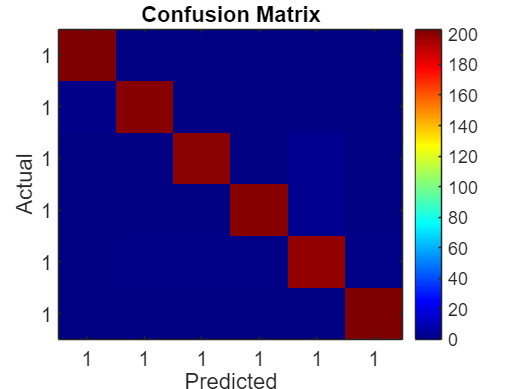

% Visualize the confusion matrix using imagesc and annotate precision
figure;
imagesc(confusionMatrix);
colorbar;
colormap('jet'); % You can change the colormap as needed
title('Confusion Matrix');
xlabel('Predicted');
ylabel('Actual');
xticks(1:numel(categories));
xticklabels(categories);
yticks(1:numel(categories));
yticklabels(categories);

% Calculate and annotate precision for each class
for i = 1:numel(categories)
    for j = 1:numel(categories)
        precision = confusionMatrix(i, i) / sum(confusionMatrix(:, i));
       text(j, i, sprintf('%.2f', precision), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'k', 'FontWeight', 'bold');
    end
end